clearvars;  
%measurement settings
format shortG
%magnet parameters
3/16

ans =        0.1875


1/8

ans =         0.125


diameter = 3/16*25.4 %mm

diameter =        4.7625


height = 1/8*25.4 %mm

height =         3.175


Br_max = 14800*0.1; %mT
mu_0 =  4*pi*10^-7*1000*1000; % mT mm/A^2
sensorheight = 35; %mm
%want M in A/m
M=Br_max;
B_t = pi*(diameter/2)^2*height*Br_max/(4*pi);
sensor_separation = 4.5; %mm
num_sensors=16;

% Parameters
y_values = -2:1:3; % Increment y from -2 to 2
x_values = -2:1:3; % Increment x from -2 to 2
z_values = 0;  % z values for 0 and 2

% Initialize the matrix to store coordinates
location = zeros(length(y_values) * length(x_values) * length(z_values), 3);

% Loop to generate coordinates
index = 1;
for y = y_values
    for x = x_values
        location(index, :) = [x, y, 0];
        index = index + 1;
    end
end


location = location(:, [2, 1, 3]).*1;

% Specify the common part of the file name
file_prefix = 'C:\Users\Brandon Nguyen\Documents\Github\magnetic-sensor-data\MLX01312024_gamma3\sensor_';
file_suffix = '_averages.csv';

% Loop to create variables sen1, sen2, ..., sen16
for sensor_num = 1:num_sensors
    % Construct the file name for the current sensor
    file_name = [file_prefix, num2str(sensor_num), file_suffix];

    try
        % Read the CSV file using readtable
        data_table = readtable(file_name, 'Delimiter', ',', 'VariableNamingRule', 'preserve');

        % Extract data matrix
        data_matrix = cell2mat(cellfun(@eval, data_table{:, :}, 'UniformOutput', false));

        % Create a variable name for the data
        variable_name = ['sen', num2str(sensor_num)];

        % Assign the data to a variable with a dynamically generated name
        eval([variable_name, ' = data_matrix;']);
    catch
        % Handle any errors (you can add specific error handling if needed)
        fprintf('Error reading data for sensor %d\n', sensor_num);
    end
end

% Number of sensors
num_sensors = 16;

% Loop over each sensor
for sensor_num = 1:num_sensors
    % Get the data for the current sensor (replace with actual data retrieval)
    d_data = eval(['sen', num2str(sensor_num)]);
    
    % Adjust the location for the magnet
    loc = location + [0, 0, 32];
    
    % Data size
    datasize = length(d_data);
    
    % Define the cost function
    dcostfun = @(v) senloc(v, loc, d_data, B_t, datasize);
    
    % Initial guess
    x0 = [0, 0, 0];
    
    % Linear constraints
    A = [];
    b = [];
    Aeq = [];
    beq = [];
    
    % Bounds
    lb = [-100, -100, -100];
    ub = [100, 100, 100];
    
    % Perform optimization and store the result in a cell
    [sensor_results{sensor_num}, fval] = fmincon(dcostfun, x0, A, b, Aeq, beq, lb, ub);
    
    % Display the result
    disp(['Sensor ', num2str(sensor_num), ' Optimization Result:']);
    disp(sensor_results{sensor_num});
    
    % Display the normalized cost
    disp(['Normalized Cost: ', num2str(fval/datasize)]);
    
    % Additional processing or storage of results can be done here
    
    % Add a separator between sensor results
    disp(repmat('-', 1, 40));
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 1 Optimization Result:


       7.9303      -6.9519      -2.9397



Normalized Cost: 1.9366e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 2 Optimization Result:


       2.8379      -6.8982      -2.5659



Normalized Cost: 1.5397e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 3 Optimization Result:


      -1.6817      -6.8481      -2.7075



Normalized Cost: 2.542e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 4 Optimization Result:


      -6.6735      -7.1909      -2.6216



Normalized Cost: 1.6709e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 5 Optimization Result:


       7.8153      -2.4724      -2.7297



Normalized Cost: 1.5356e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 6 Optimization Result:


       2.8943       -2.164      -2.6983



Normalized Cost: 1.8132e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 7 Optimization Result:


      -1.9481      -2.3316      -2.2156



Normalized Cost: 1.9093e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 8 Optimization Result:


      -6.9813       -1.928      -2.5098



Normalized Cost: 2.0471e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 9 Optimization Result:


       7.8833       2.9037      -2.4926



Normalized Cost: 1.5796e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 10 Optimization Result:


        2.735       2.6344      -2.4552



Normalized Cost: 1.5612e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 11 Optimization Result:


      -1.7957       2.7486      -2.3259



Normalized Cost: 1.8243e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 12 Optimization Result:


      -6.8155       2.6859      -2.6777



Normalized Cost: 2.6116e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 13 Optimization Result:


        7.786       7.3886      -2.7212



Normalized Cost: 1.6712e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 14 Optimization Result:


       2.9169       7.2455      -2.3992



Normalized Cost: 1.7371e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 15 Optimization Result:


      -1.8792       7.2778      -2.3182



Normalized Cost: 2.1231e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 16 Optimization Result:


      -6.6807       7.6077      -2.6135



Normalized Cost: 2.2797e-05


----------------------------------------



% Assign the results to sensor1, sensor2, ...
for sensor_num = 1:num_sensors
    eval(['sensor', num2str(sensor_num), ' = sensor_results{', num2str(sensor_num), '};']);
end

% Initialize arrays to store X and Y coordinates
x_coordinates = zeros(1, num_sensors);
y_coordinates = zeros(1, num_sensors);

% Extract X and Y coordinates from sensor_results
for sensor_num = 1:num_sensors
    eval(['sensor', num2str(sensor_num), ' = sensor_results{', num2str(sensor_num), '};']);
    x_coordinates(sensor_num) = eval(['sensor', num2str(sensor_num), '(1);']);
    y_coordinates(sensor_num) = eval(['sensor', num2str(sensor_num), '(2);']);
end

% Sensor locations in the 4x4 grid
sensor_grid = [
    0, 0;
    -4.5, 0;
    -9.0, 0;
    -13.5, 0;
    0, 4.5;
    -4.5, 4.5;
    -9.0, 4.5;
    -13.5, 4.5;
    0, 9.0;
    -4.5, 9.0;
    -9.0, 9.0;
    -13.5, 9.0;
    0, 13.5;
    -4.5, 13.5;
    -9.0, 13.5;
    -13.5, 13.5
];

sensor_grid = sensor_grid + [13.5/2 -13.5/2]

sensor_grid =          6.75        -6.75
         2.25        -6.75
        -2.25        -6.75
        -6.75        -6.75
         6.75        -2.25
         2.25        -2.25
        -2.25        -2.25
        -6.75        -2.25
         6.75         2.25
         2.25         2.25


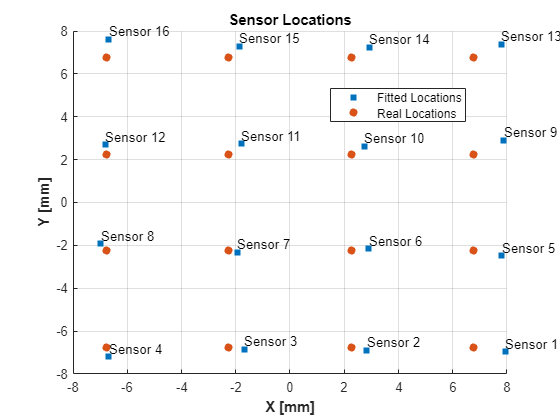


% Plot X and Y coordinates
figure;
scatter(x_coordinates, y_coordinates, 's', 'filled', 'DisplayName', 'Fitted Locations');
hold on;
scatter(sensor_grid(:, 1), sensor_grid(:, 2), 'filled', 'DisplayName', 'Real Locations');
legend('Location', 'Best');
title('Sensor Locations');
xlabel('X [mm]', 'FontWeight','bold');
ylabel('Y [mm]', 'FontWeight','bold');
grid on;
hold off;

% Annotate points with sensor names
for sensor_num = 1:num_sensors
    sensor_name = ['Sensor ', num2str(sensor_num)];
    text(x_coordinates(sensor_num), y_coordinates(sensor_num), sensor_name, 'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');
end

corr_x = mean(x_coordinates - sensor_grid(:,1)')

corr_x =       0.52146


corr_y = mean(y_coordinates - sensor_grid(:,2)')

corr_y =       0.23168


sensor_actual = [
    0, 0, 0;
    -4.5, 0, 0;
    -9.0, 0, 0;
    -13.5, 0, 0;
    0, 4.5, 0;
    -4.5, 4.5, 0;
    -9.0, 4.5, 0;
    -13.5, 4.5, 0;
    0, 9.0, 0;
    -4.5, 9.0, 0;
    -9.0, 9.0, 0;
    -13.5, 9.0, 0;
    0, 13.5, 0;
    -4.5, 13.5, 0;
    -9.0, 13.5, 0;
    -13.5, 13.5, 0
];

sensor_actual = sensor_actual + [13.5/2 -13.5/2 0];

% Loop over each sensor
for sensor_num = 1:num_sensors
    % Get the data for the current sensor (replace with actual data retrieval)
    d_data = eval(['sen', num2str(sensor_num)]);
    sensor = eval(['sensor', num2str(sensor_num)]);
    
    % Data size
    datasize = length(d_data);
    
    % Define the cost function
    dcostfun = @(v) anglecost(v, loc, d_data, B_t, datasize, sensor);
    
    % Nonlinear constraints
    nonlcon = @con;

    % Initial guess
    x0 = [0, 0, 0];

    % Linear constraints
    A = [];
    b = [];
    Aeq = [];
    beq = [];

    % Bounds
    lb = [-1, -1, -1];
    ub = [1, 1, 1];

    % Perform optimization
    [angle_results{sensor_num}, fval] = fmincon(dcostfun, x0, A, b, Aeq, beq, lb, ub, nonlcon);

    % Display the result
    disp(['Sensor ', num2str(sensor_num), ' Angle Optimization Result:']);
    disp(angle_results{sensor_num});
    
    % Display the normalized cost
    disp(['Normalized Cost: ', num2str(fval/datasize)]);
    
    % Additional processing or storage of results can be done here
    
    % Add a separator between sensor results
    disp(repmat('-', 1, 40));
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 1 Angle Optimization Result:


  -0.00021067  -0.00081408           -1



Normalized Cost: 1.937e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 2 Angle Optimization Result:


   5.3704e-05  -0.00088153           -1



Normalized Cost: 1.5395e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 3 Angle Optimization Result:


  -0.00060534  -0.00081475           -1



Normalized Cost: 2.5413e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 4 Angle Optimization Result:


  -0.00061059  -0.00042735           -1



Normalized Cost: 1.6713e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 5 Angle Optimization Result:


    0.0002007   0.00073769           -1



Normalized Cost: 1.5357e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 6 Angle Optimization Result:


  -0.00064873   9.2398e-05           -1



Normalized Cost: 1.8139e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 7 Angle Optimization Result:


  -0.00064738   0.00027514           -1



Normalized Cost: 1.9098e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 8 Angle Optimization Result:


   -0.0001399  -0.00078014           -1



Normalized Cost: 2.0474e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 9 Angle Optimization Result:


  -0.00047889    0.0006695           -1



Normalized Cost: 1.5798e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 10 Angle Optimization Result:


  -0.00072873  -9.5363e-05           -1



Normalized Cost: 1.5616e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 11 Angle Optimization Result:


  -0.00083258  -9.8373e-05           -1



Normalized Cost: 1.8242e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 12 Angle Optimization Result:


  -0.00082113  -1.8875e-05           -1



Normalized Cost: 2.6118e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 13 Angle Optimization Result:


  -0.00014612   0.00097324           -1



Normalized Cost: 1.671e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 14 Angle Optimization Result:


  -0.00032078    0.0010551           -1



Normalized Cost: 1.7358e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 15 Angle Optimization Result:


  -0.00075433   0.00077526           -1



Normalized Cost: 2.1218e-05


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 16 Angle Optimization Result:


  -0.00090669   2.6985e-05           -1



Normalized Cost: 2.2796e-05


----------------------------------------



% Assign the results to sensor1, sensor2, ...
for sensor_num = 1:num_sensors
    eval(['angle', num2str(sensor_num), ' = angle_results{', num2str(sensor_num), '};']);
end

% Loop to fit locations for the magnet using the angle obtained
for sensor_num = 1:num_sensors
    % Create a variable name for the data
    senave = eval(['sen', num2str(sensor_num)]);
    senlocs = eval(['sensor', num2str(sensor_num)]);
    mangle = eval(['angle', num2str(sensor_num)]);
    loc_corr = eval(['sensor_actual(', num2str(sensor_num),',:)']);

    % Fitting for location using the angle obtained
    sen_preds = [];
    sen_fvals = [];
    locavg = [loc, senave];

    for t = 1:length(d_data)
        B_data = locavg(t, 4:6);
        costfun = @(v)loccost(v, mangle, B_data, B_t, senlocs);
        nonlcon = @con;

        x0 = [0, 0, 35];
        A = [];
        b = [];
        Aeq = [];
        beq = [];
        lb = [-100, -100, 0];
        ub = [100, 100, 100];
        [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
        sen_preds = [sen_preds; locs];
        sen_fvals = [sen_fvals; fval];
    end
    %sen_preds = sen_preds - loc_corr;
    % Save the results
    variable_name_preds = ['sen', num2str(sensor_num), '_preds'];
    variable_name_fvals = ['sen', num2str(sensor_num), '_fvals'];
    eval([variable_name_preds, ' = sen_preds;']);
    eval([variable_name_fvals, ' = sen_fvals;']);
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

sen1_preds

sen1_preds =       -2.2677      -2.1551       31.906
      -2.4642      -1.0421       31.859
      -2.3292     0.099124       31.978
      -2.1163       1.1499       32.032
      -2.2251       2.2541       31.987
      -2.3197       3.2824       31.908
      -1.3372      -2.1858       31.928
      -1.2065      -1.2239       31.909
      -1.3375     0.045308       31.947
       -1.397       1.1424       32.086


sen1_fvals

sen1_fvals =    6.2363e-10
   8.0244e-10
   9.6073e-10
   1.7729e-10
   1.1647e-09
   1.0349e-11
   2.2679e-10
   5.8672e-11
   1.0996e-10
   3.7274e-10


fixadiff = sen1_preds - loc

fixadiff =      -0.26765      -0.1551    -0.093927
     -0.46424    -0.042083     -0.14059
     -0.32925     0.099124    -0.022235
     -0.11632      0.14985     0.032142
     -0.22515      0.25409    -0.012668
     -0.31969      0.28235    -0.092034
     -0.33717      -0.1858    -0.072301
     -0.20645     -0.22391     -0.09083
     -0.33749     0.045308    -0.052889
     -0.39704      0.14241     0.086459


max(fixadiff)

ans =       0.39799       0.3636      0.19926


min(fixadiff)

ans =      -0.46424     -0.37124     -0.16323


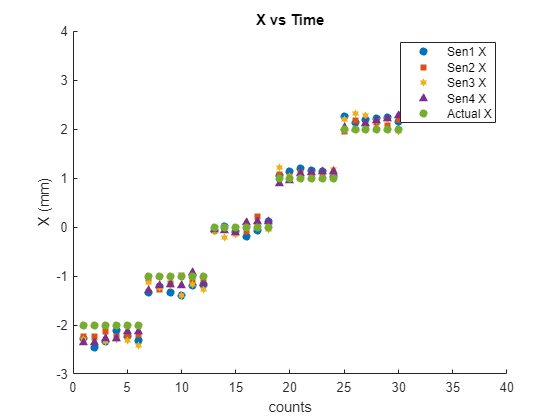

ss1 = sortrows(sen1_preds, 1, 'descend');
ss2 = sortrows(sen2_preds, 1, 'descend');
ss3 = sortrows(sen3_preds, 1, 'descend');
ss4 = sortrows(sen4_preds, 1, 'descend');
ll = sortrows(loc,1, 'descend');
%predicted location using fixed angle
scatter(1:length(sen1_preds),sen1_preds(:,1), 'filled') %x values
hold on;
scatter(1:length(sen2_preds),sen2_preds(:,1), 'filled','square')
scatter(1:length(sen3_preds),sen3_preds(:,1), 'filled','hexagram')
scatter(1:length(sen4_preds),sen4_preds(:,1), 'filled','^')
%title('X vs Time')
xlabel('counts')
ylabel('X (mm)')
%ylim([0,4])

scatter(1:length(sen1_preds),loc(:,1), 'filled')
title('X vs Time')
xlabel('counts')
ylabel('X (mm)')
%ylim([-2,2])
legend('Sen1 X','Sen2 X','Sen3 X','Sen4 X', 'Actual X')
hold off;


% scatter(1:length(sen1_preds),ss1(:,1), 'filled') %x values
% hold on;
% scatter(1:length(sen2_preds),ss2(:,1), 'filled','square')
% scatter(1:length(sen3_preds),ss3(:,1), 'filled','hexagram')
% scatter(1:length(sen4_preds),ss4(:,1), 'filled','^')
% %title('X vs Time')
% xlabel('counts')
% ylabel('X (mm)')
%ylim([0,4])

% scatter(1:length(sen1_preds),ll(:,1), 'filled')
% title('X Location Comparison')
% xlabel('counts')
% ylabel('X (mm)')
% %ylim([-2,2])
% legend('Sen1 X','Sen2 X','Sen3 X','Sen4 X', 'Actual X')
% hold off;


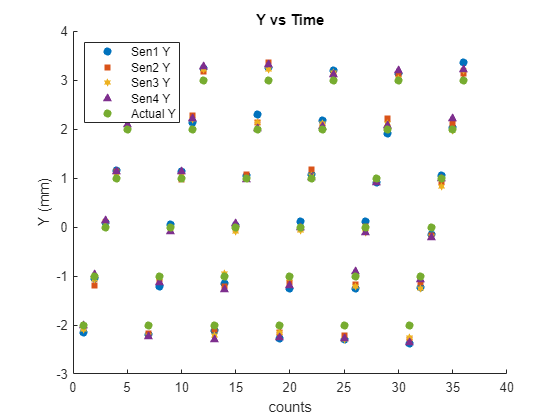

scatter(1:length(sen1_preds),sen1_preds(:,2), 'filled') %y values
hold on;
scatter(1:length(sen1_preds),sen2_preds(:,2), 'filled','square')
scatter(1:length(sen1_preds),sen3_preds(:,2), 'filled','hexagram')
scatter(1:length(sen1_preds),sen4_preds(:,2), 'filled','^')
%title('Fitted Y vs Time')
xlabel('counts')
ylabel('Y (mm)')
%ylim([-1,3])

scatter(1:length(sen1_preds),loc(:,2), 'filled')
title('Y vs Time')
xlabel('counts')
ylabel('Y (mm)')
%ylim([-2,2])
legend('Sen1 Y','Sen2 Y','Sen3 Y','Sen4 Y', 'Actual Y', Location='northwest')
hold off;

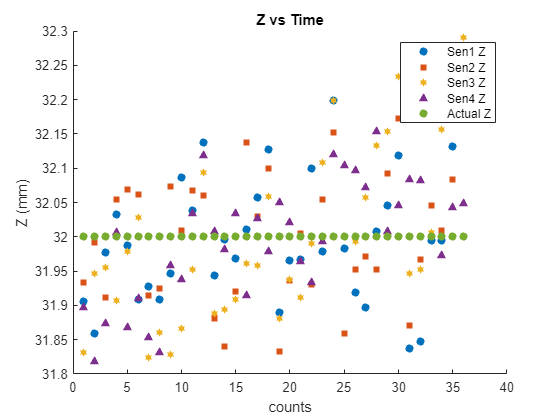

scatter(1:length(sen1_preds),sen1_preds(:,3), 'filled') %z values
hold on;
scatter(1:length(sen1_preds),sen2_preds(:,3), 'filled','square')
scatter(1:length(sen1_preds),sen3_preds(:,3), 'filled','hexagram')
scatter(1:length(sen1_preds),sen4_preds(:,3), 'filled','^')
%title('Fitted Z vs Time')
xlabel('counts')
ylabel('Z (mm)')
%ylim([39,43])
% scatter(1:length(locavg1),fixadiff(:,1))
% scatter(1:length(locavg1),fixadiff(:,2))
% scatter(1:length(locavg1),fixadiff(:,3))

%actual location of measurement


scatter(1:length(sen1_preds),loc(:,3), 'filled')
title('Z vs Time')
xlabel('counts')
ylabel('Z (mm)')
legend('Sen1 Z','Sen2 Z','Sen3 Z','Sen4 Z', 'Actual Z')
hold off;

01312024

calculate magnetic field strengths of other magnets - find combination with largets magnetic field strength 

Redo measurements closer to sensor (maybe try n52 right away)

Use smallest magnet "reasonably" detecable at 2 cm. (just measure all of them at 2cm)

    Use strongest magnet, play with z-distance, decreae

Try fitting with center 4 sensors only

sen1_preds

sen1_preds =       -2.2677      -2.1551       31.906
      -2.4642      -1.0421       31.859
      -2.3292     0.099124       31.978
      -2.1163       1.1499       32.032
      -2.2251       2.2541       31.987
      -2.3197       3.2824       31.908
      -1.3372      -2.1858       31.928
      -1.2065      -1.2239       31.909
      -1.3375     0.045308       31.947
       -1.397       1.1424       32.086


sen1_fvals

sen1_fvals =    6.2363e-10
   8.0244e-10
   9.6073e-10
   1.7729e-10
   1.1647e-09
   1.0349e-11
   2.2679e-10
   5.8672e-11
   1.0996e-10
   3.7274e-10


fixadiff = sen1_preds - loc

fixadiff =      -0.26765      -0.1551    -0.093927
     -0.46424    -0.042083     -0.14059
     -0.32925     0.099124    -0.022235
     -0.11632      0.14985     0.032142
     -0.22515      0.25409    -0.012668
     -0.31969      0.28235    -0.092034
     -0.33717      -0.1858    -0.072301
     -0.20645     -0.22391     -0.09083
     -0.33749     0.045308    -0.052889
     -0.39704      0.14241     0.086459


max(fixadiff)

ans =       0.39799       0.3636      0.19926


min(fixadiff)

ans =      -0.46424     -0.37124     -0.16323


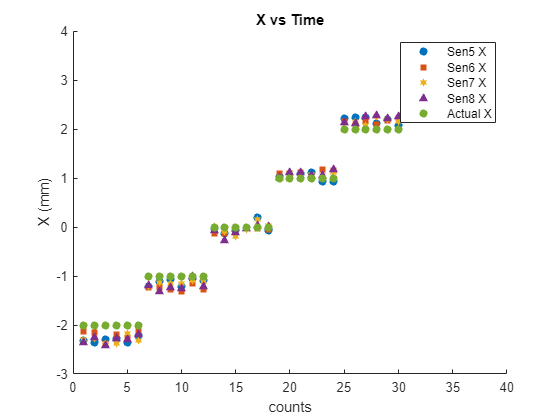

ss1 = sortrows(sen5_preds, 1, 'descend');
ss2 = sortrows(sen6_preds, 1, 'descend');
ss3 = sortrows(sen7_preds, 1, 'descend');
ss4 = sortrows(sen8_preds, 1, 'descend');
ll = sortrows(loc,1, 'descend');
%predicted location using fixed angle
scatter(1:length(sen5_preds),sen5_preds(:,1), 'filled') %x values
hold on;
scatter(1:length(sen6_preds),sen6_preds(:,1), 'filled','square')
scatter(1:length(sen7_preds),sen7_preds(:,1), 'filled','hexagram')
scatter(1:length(sen8_preds),sen8_preds(:,1), 'filled','^')
%title('X vs Time')
xlabel('counts')
ylabel('X (mm)')
%ylim([0,4])

scatter(1:length(sen1_preds),loc(:,1), 'filled')
title('X vs Time')
xlabel('counts')
ylabel('X (mm)')
%ylim([-2,2])
legend('Sen5 X','Sen6 X','Sen7 X','Sen8 X', 'Actual X')
hold off;


% scatter(1:length(sen1_preds),ss1(:,1), 'filled') %x values
% hold on;
% scatter(1:length(sen2_preds),ss2(:,1), 'filled','square')
% scatter(1:length(sen3_preds),ss3(:,1), 'filled','hexagram')
% scatter(1:length(sen4_preds),ss4(:,1), 'filled','^')
% %title('X vs Time')
% xlabel('counts')
% ylabel('X (mm)')
%ylim([0,4])

% scatter(1:length(sen1_preds),ll(:,1), 'filled')
% title('X Location Comparison')
% xlabel('counts')
% ylabel('X (mm)')
% %ylim([-2,2])
% legend('Sen1 X','Sen2 X','Sen3 X','Sen4 X', 'Actual X')
% hold off;


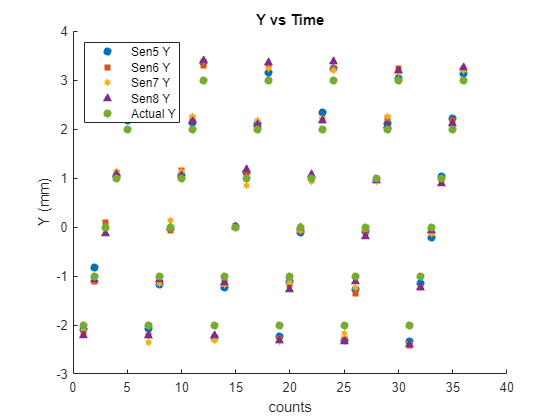

scatter(1:length(sen1_preds),sen5_preds(:,2), 'filled') %y values
hold on;
scatter(1:length(sen1_preds),sen6_preds(:,2), 'filled','square')
scatter(1:length(sen1_preds),sen7_preds(:,2), 'filled','hexagram')
scatter(1:length(sen1_preds),sen8_preds(:,2), 'filled','^')
%title('Fitted Y vs Time')
xlabel('counts')
ylabel('Y (mm)')
%ylim([-1,3])

scatter(1:length(sen1_preds),loc(:,2), 'filled')
title('Y vs Time')
xlabel('counts')
ylabel('Y (mm)')
%ylim([-2,2])
legend('Sen5 Y','Sen6 Y','Sen7 Y','Sen8 Y', 'Actual Y', Location='northwest')
hold off;

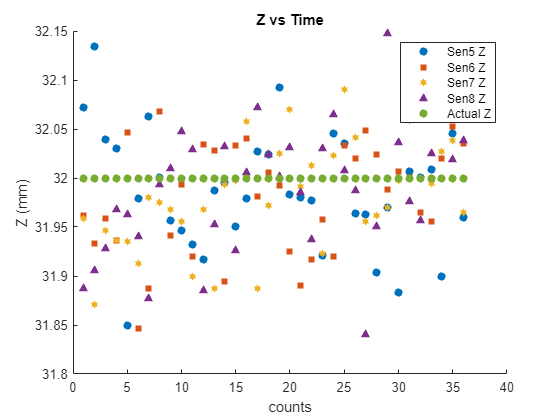

scatter(1:length(sen1_preds),sen5_preds(:,3), 'filled') %z values
hold on;
scatter(1:length(sen1_preds),sen6_preds(:,3), 'filled','square')
scatter(1:length(sen1_preds),sen7_preds(:,3), 'filled','hexagram')
scatter(1:length(sen1_preds),sen8_preds(:,3), 'filled','^')
%title('Fitted Z vs Time')
xlabel('counts')
ylabel('Z (mm)')
%ylim([39,43])
% scatter(1:length(locavg1),fixadiff(:,1))
% scatter(1:length(locavg1),fixadiff(:,2))
% scatter(1:length(locavg1),fixadiff(:,3))

%actual location of measurement


scatter(1:length(sen1_preds),loc(:,3), 'filled')
title('Z vs Time')
xlabel('counts')
ylabel('Z (mm)')
legend('Sen5 Z','Sen6 Z','Sen7 Z','Sen8 Z', 'Actual Z')
hold off;

sensor1

sensor1 =        7.9303      -6.9519      -2.9397


sensor2

sensor2 =        2.8379      -6.8982      -2.5659


sensor3

sensor3 =       -1.6817      -6.8481      -2.7075


sensor4

sensor4 =       -6.6735      -7.1909      -2.6216



angle1

angle1 =   -0.00021067  -0.00081408           -1


angle2

angle2 =    5.3704e-05  -0.00088153           -1


angle3

angle3 =   -0.00060534  -0.00081475           -1


angle4

angle4 =   -0.00061059  -0.00042735           -1



sensor_3DA = sensor_actual + sensor11.*[1 1 0] - sensor_actual(11,:)

sensor_3DA =        7.2043      -6.2514            0
       2.7043      -6.2514            0
      -1.7957      -6.2514            0
      -6.2957      -6.2514            0
       7.2043      -1.7514            0
       2.7043      -1.7514            0
      -1.7957      -1.7514            0
      -6.2957      -1.7514            0
       7.2043       2.7486            0
       2.7043       2.7486            0



% Create a cell array to store all rows
all_sen = cell(length(d_data), 16);

% Access each row of each matrix and store in the cell array
for row = 1:length(d_data)
    for sensor = 1:16
        sens = eval(['sen', num2str(sensor)]);
        all_sen{row, sensor} = sens(row,:);
    end
end

all_sen

all_sen = 36×16 cell array
    {[  0.10784 -0.05061 -0.23273]}    {[0.064725 -0.061845 -0.28704]}    {[  0.00819 -0.063495 -0.30538]}    {[-0.055305 -0.066315 -0.28936]}    {[  0.11259 -0.00441 -0.24686]}    {[   0.066105 -6e-05 -0.30054]}    {[ 0.005115 -0.003825 -0.33365]}    {[ -0.063045 0.003915 -0.31015]}    {[  0.11149 0.05628 -0.23897]}    {[   0.06408 0.06183 -0.2896]}    {[    0.006885 0.06777 -0.3107]}    {[ -0.056115 0.06048 -0.28646]}    {[ 0.09507 0.08793 -0.20028]}    {[  0.05742 0.10225 -0.24643]}    {[ 0.004155 0.11263 -0.26557]}    {[ -0.048495 0.10883 -0.24466]}
    {[   0.1072 -0.06084 -0.22506]}    {[     0.063 -0.07086 -0.2797]}    {[  0.008625 -0.07455 -0.29451]}    {[   -0.05436 -0.07851 -0.2829]}    {[  0.11159 -0.01809 -0.24384]}    {[ 0.066435 -0.01374 -0.30025]}    {[   0.00486 -0.018615 -0.3349]}    {[  -0.06411 -0.01146 -0.30845]}    {[ 0.11335 0.043155 -0.24316]}    {[0.064305 0.048435 -0.29906]}    {[    0.00762 0.05403 -0.32084]}    {[  -0.0573 0.048975 

multipreds = [];
multifvals = [];
for t = 1:length(sen1)
        tt = [all_sen{t,:}];
        costfun = @(v)mmcost(v, B_t, sensor_actual, tt, 1, 16);
        nonlcon = @con;

        x0 = [0, 0, 0, 5, 5, 55];
        A = [];
        b = [];
        Aeq = [];
        beq = [];
        lb = [-1, -1, -1, -100, -100, 0];
        ub = [1, 1, 1, 100, 100, 100];
        [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
        multipreds = [multipreds; locs];
        multifvals = [multifvals; fval];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

multiang = multipreds(:,1:3)

multiang =      0.051114    -0.012855     -0.79642
     0.049537     -0.02892     -0.78897
     0.048101    -0.047353     -0.79195
     0.044455    -0.083618     -0.80199
     0.056747    -0.083841     -0.78204
     0.014202    -0.086962     -0.78403
     0.069659   -0.0047137     -0.78603
     0.058255    -0.022947     -0.80276
     0.035341    -0.041452     -0.79565
     0.053049    -0.081453     -0.79128


multiloc = multipreds(:,4:6) + [corr_x corr_y 0]

multiloc =       -2.7956       -1.756       31.972
      -2.7775     -0.54591       31.853
      -2.7529      0.71633       31.891
       -2.678       2.2261       32.011
      -2.8505       3.2393       31.708
      -2.2182       4.2924       31.726
      -2.0418      -1.9727       31.832
      -1.8796      -0.7003       32.078
      -1.5539      0.59428       31.972
      -1.8038        2.162       31.892


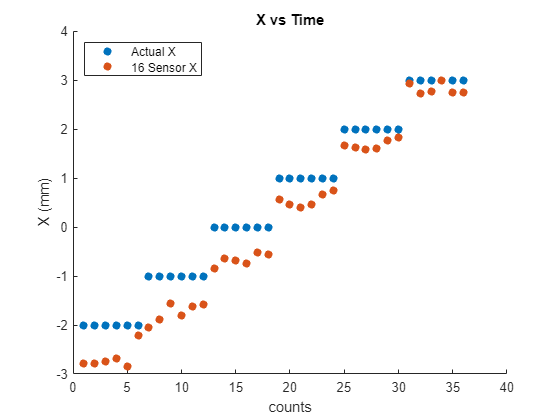

scatter(1:length(sen1_preds),loc(:,1), 'filled')
hold on;
scatter(1:length(sen1_preds), multiloc(:,1), 'filled')
title('X vs Time')
xlabel('counts')
ylabel('X (mm)')
ylim([-3,4])
legend('Actual X','16 Sensor X', Location='northwest')
hold off;

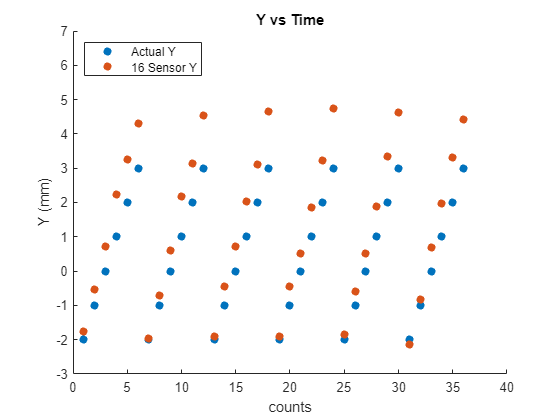

scatter(1:length(sen1_preds),loc(:,2), 'filled')
hold on;
scatter(1:length(sen1_preds), multiloc(:,2), 'filled')
title('Y vs Time')
xlabel('counts')
ylabel('Y (mm)')
ylim([-3,7])
legend('Actual Y','16 Sensor Y', Location='northwest')
hold off;

testx =sqrt(sum((multiloc-[-2.7977 -1.7384 31.969+5]).^2, 2))

testx =        4.9971
       5.2536
       5.6407
       6.3495
       7.2428
       8.0122
       5.1979
       5.0837
       5.6532
        6.479


zi = [5.000
5.099
5.385
5.831
6.403
7.071
5.099
5.196
5.477
5.916
6.481
7.141
5.385
5.477
5.745
6.164
6.708
7.348
5.831
5.916
6.164
6.557
7.071
7.681
6.403
6.481
6.708
7.071
7.550
8.124
7.071
7.141
7.348
7.681
8.124
8.660
]

zi =             5
        5.099
        5.385
        5.831
        6.403
        7.071
        5.099
        5.196
        5.477
        5.916


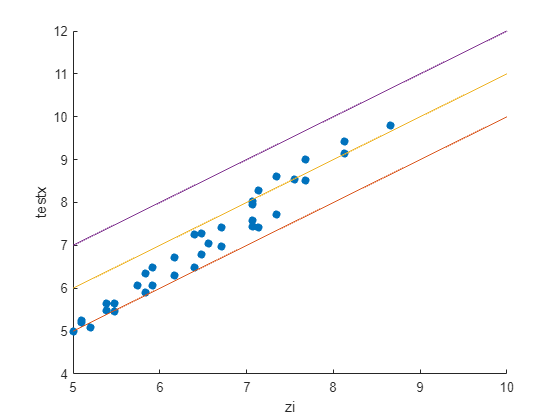


scatter(zi, testx, 'filled')
hold on;
plot(5:10, 5:10)
plot(5:10, 6:11)
plot(5:10, 7:12)
xlabel("zi")
ylabel('testx')
hold off;

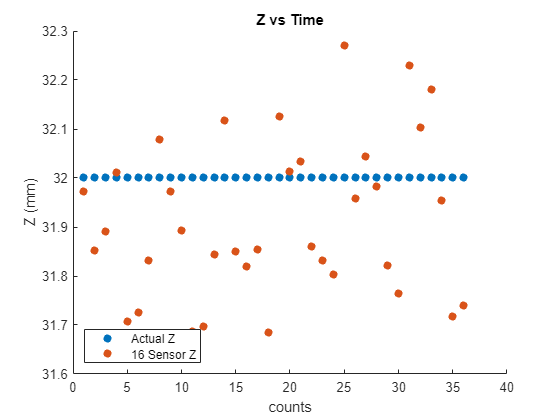

scatter(1:length(sen1_preds),loc(:,3), 'filled')
hold on;
scatter(1:length(sen1_preds), multiloc(:,3), 'filled')
title('Z vs Time')
xlabel('counts')
ylabel('Z (mm)')
%ylim([31,33])
legend('Actual Z','16 Sensor Z', Location='southwest')
hold off;

test = diff(multiloc(:,1))

test =      0.018057
      0.02466
     0.074924
     -0.17257
       0.6323
      0.17641
       0.1622
      0.32575
     -0.24998
      0.18609


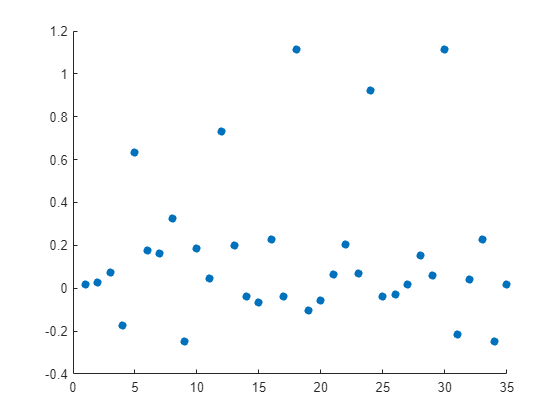

scatter(1:length(test), test, 'filled')
hold on;
hold off;

multidisp = multiloc + [2 2 -27]

multidisp =       -0.7956      0.24397       4.9719
     -0.77754       1.4541       4.8526
     -0.75288       2.7163       4.8906
     -0.67796       4.2261       5.0106
     -0.85053       5.2393        4.708
     -0.21823       6.2924        4.726
     -0.04182     0.027336       4.8316
      0.12038       1.2997       5.0778
      0.44613       2.5943        4.972
      0.19616        4.162        4.892


multidisp = sqrt(sum(multidisp.^2, 2))

multidisp =        5.0411
       5.1251
       5.6448
       6.5898
       7.0949
       7.8725
       4.8319
       5.2429
       5.6258
       6.4259



disp = [4.98 5.08 5.35 5.78 6.34 7.01 5.08 5.18 5.45 5.9 6.46 7.12 5.37 5.47 5.74 6.13 6.66 7.3 5.81 5.91 6.15 6.55 7.05 7.67 6.41 6.47 6.70 7.05 7.55 8.11 7.06 7.13 7.34 7.67 8.1 8.65]'

disp =          4.98
         5.08
         5.35
         5.78
         6.34
         7.01
         5.08
         5.18
         5.45
          5.9


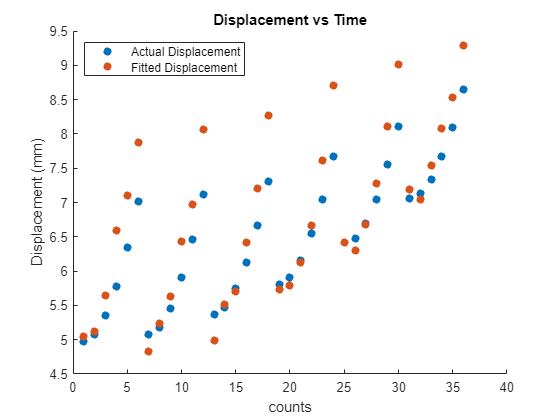


scatter(1:length(disp), disp, 'filled')
hold on;
scatter(1:length(multidisp), multidisp, 'filled')
title('Displacement vs Time')
xlabel('counts')
ylabel('Displacement (mm)')
legend('Actual Displacement', 'Fitted Displacement', Location='northwest')
hold off;

function a = anglecost(v, loc, B_data, B_t, datasize, sensor)
X1 = sensor - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], datasize, 1);
a = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function [c, ceq] = con(v)
c = [];
ceq = sqrt(sum([v(1) v(2) v(3)].^2, 2)) - 1;
end

function b = loccost(x, angle, B_data, B_t, sensor)
X1 = sensor - [x(1) x(2) x(3)];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem(angle, 1, 1);
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function b = bothcost(v, B_data, B_t)
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X1 = [-v(4) -v(5) -v(6)];
R1 = sqrt(sum(X1.^2, 2));
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function s = senloc(x, loc, B_data, B_t, datasize)
X1 = [x(1) x(2) x(3)] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 -1], datasize, 1);
s = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function m = multicost(v, sen1, sen2, sen3, sen4, B_t)
loc = [v(4) v(5) v(6)];
X1 = [0 0 0] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X2 = [-25 0 0] - loc;
R2 = sqrt(sum(X2.^2, 2));
X3 = [0 25 0] - loc;
R3 = sqrt(sum(X3.^2, 2));
X4 = [-25 25 0] - loc;
R4 = sqrt(sum(X4.^2, 2));
m = sum(sum((sen1 - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2) + sum((sen2 - B_t*(3*dot(H_0, X2, 2).*X2./R2.^5-H_0./R2.^3)).^2) ...
    + sum((sen3 - B_t*(3*dot(H_0, X3, 2).*X3./R3.^5-H_0./R3.^3)).^2) + sum((sen4 - B_t*(3*dot(H_0, X4, 2).*X4./R4.^5-H_0./R4.^3)).^2));
end

function mm = mmcost(v, B_t, sensor_grid, sensor_data, s1, s2)
    H_0 = repelem([v(1) v(2) v(3)], 1, 1);
    loc = [v(4) v(5) v(6)];
    s = sensor_data;
    mm = 0;
    for i = s1:s2
        X = sensor_grid(i, :) - loc;
        R = sqrt(sum(X.^2, 2));
        mm = mm + sum((s(3*i-2:3*i) - B_t * (3 * dot(H_0, X, 2) .* X ./ R.^5 - H_0 ./ R.^3)).^2);
    end
end